# visualizing b_sec at one time - 3d

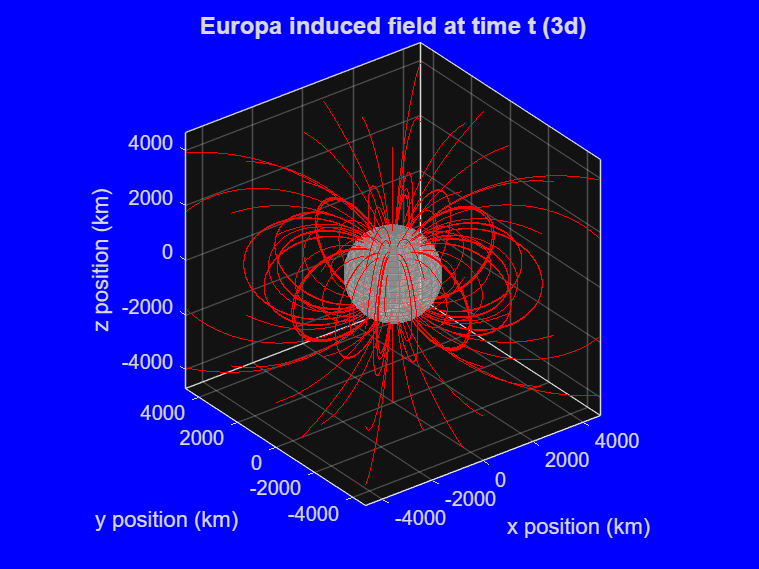

clear
% define constants

r_m = 1560; % Europa radius (km)
B_prim = 250; % approximate background field amplitude nT
A = 0.95; % amplitude response factor
phi = 0.14; % phase lag in radians (around 8 deg)
omega = 2*pi / (11.23 * 3600); % synodic freq. (rad/sec), 11.23 hr period

t = 0;

% inducing field direction(fixed for now)
e0 = [0;0;1];

% create spatial grid (x-z plane)
grid_limit = 3 * r_m; % view up to 3 planetary radii out 
[X,Y,Z] = meshgrid(linspace(-grid_limit, grid_limit, 30), ...
    linspace(-grid_limit,grid_limit, 30), ...
    linspace(-grid_limit, grid_limit, 30));


% compute secondary field components (bx,by,bz) at every point 
% initialize arrays to hold magnetic field vector components

Bx_spatial = zeros(size(X));
By_spatial = zeros(size(X));
Bz_spatial = zeros(size(X));

% loop through each grid point to calculate the spatial part of eqn (3)
for i = 1:numel(X);

    % define position vector r from center of moon
    r_vec = [X(i); Y(i); Z(i)];
    r = norm(r_vec);

    % mask field inside the moon to avoid division by 0
    if r < r_m;
        continue;
    end

    % calculate dot prod (r . e0)
    r_dot_e0 = dot(r_vec, e0);

    % evaluate spatial vector bracket: 3*(r . e0)*r - (r^2)*e0
    spatial_bracket = 3 * r_dot_e0 * r_vec - (r^2) * e0;

    % compute spatial coefficient: - (A * B_prim * r_m^3) / (2 * r^5)
    coef = - (A *B_prim * r_m^3) / (2 *r^5);

    % store vector components
    B_vector = coef * spatial_bracket;
    Bx_spatial(i) = B_vector(1);
    By_spatial(i) = B_vector(2);
    Bz_spatial(i) = B_vector(3);    

end


period = 2*pi / omega; % total cycle time in seconds


figure('Color', 'b');
set(gcf, 'Position', [100, 100, 800, 600]);
hold on;

% stream seeds in 3d
[seed_X, seed_Y, seed_Z] = meshgrid(linspace(-1.8*r_m, 1.8*r_m, 5), ...
    linspace(-1.8*r_m, 1.8*r_m, 5), linspace(-1.8*r_m, 1.8*r_m, 5));



time_factor = cos(omega * t - phi);

% apply scalar factor to pre-calculated spatial field components
Bx = Bx_spatial * time_factor;
By = By_spatial * time_factor;
Bz = Bz_spatial * time_factor;


% draw Europa as 3d sphere
[sx, sy, sz] = sphere(24);
mesh(sx*r_m, sy*r_m, sz*r_m, 'FaceColor', [0.8 0.8 0.8], 'EdgeColor',[0.5 0.5 0.5]);
alpha(0.4);


% plot mag field vectors
h1 = streamline(X,Y,Z,Bx,By,Bz,seed_X(:), seed_Y(:), seed_Z(:));
h2 = streamline(X,Y,Z,-Bx,-By,-Bz,seed_X(:), seed_Y(:), seed_Z(:));


set(h1, 'Color', 'r', 'LineWidth', 0.5);
set(h2, 'Color', 'r', 'LineWidth', 0.5);

% grid formatting
axis equal; 
xlim([-grid_limit, grid_limit]);
ylim([-grid_limit, grid_limit]);
zlim([-grid_limit, grid_limit]);
xlabel('x position (km)', 'FontSize', 11);
ylabel('y position (km)', 'FontSize', 11);
zlabel('z position (km)', 'FontSize', 11);
title('Europa induced field at time t (3d)', 'FontSize', 12);
grid on;
box on;
    
view(3);
rotate3d on;




% magnetic dipole always aligns itself with the field that created it
% in this case, e0 = [0,0,1], so r . e0 = z
